# Live Script for Disinflation IRFs with Simple NK-Model

## Initialization

clear all
close all
clc

## Select the Model for Dynare

% model_name = 'NKmodel_baseline_v2';
% model_name = 'longterm_debt';
% model_name = 'Simple_surplus_rule';
% model_name = 'longterm_debt_surplus_rule';
model_name = 'NK_SS';
% model_name = 'NK_SS_LTB';
% model_name = 'NK_CS';
% model_name = 'NK_CS_LTB';


eval(['dynare ', model_name, '.mod noclearall nostrict nolog']);

Configuring Dynare ...
[mex] Generalized QZ.
[mex] Sylvester equation solution.
[mex] Kronecker products.
[mex] Sparse kronecker products.
[mex] Local state space iteration (second order).
[mex] Bytecode evaluation.
[mex] k-order perturbation solver.
[mex] k-order solution simulation.
[mex] Quasi Monte-Carlo sequence (Sobol).
[mex] Markov Switching SBVAR.

Using 64-bit preprocessor
Starting Dynare (version 4.5.6).
Starting preprocessing of the model file ...
Found 6 equation(s).
Evaluating expressions...done
Computing static model derivatives:
 - order 1
Computing dynamic model derivatives:
 - order 1
 - order 2
Processing outputs ...
done
Preprocessing completed.


STEADY-STATE RESULTS:

pi 		 0.08
x  		 -4.33681e-19
i  		 0.0900503
v  		 4.0817e-17
s  		 4.0817e-19
r  		 0

EIGENVALUES:
         Modulus             Real        Imaginary

          0.2897           0.2897                0
          0.6566           0.6566                0
           1.655            1.655             

warning('off', 'MATLAB:singularMatrix');

folder_path = fullfile(pwd, model_name); % 'pwd' ensures an absolute path from the current working directory
if ~exist(folder_path, 'dir')
   mkdir(folder_path);
end

% Load the estimated posterior paramters from Dynare
% addpath("SW_LTB_RR\metropolis");
% load("SW_LTB_RR_mh1_blck1.mat");

## Setting the Parameters

inflation_target = 0.02;
Tstar = 6; %default Ta = 4

### Fiscal-led regime

CRPI_fis = 0.5;
R_fis = 0;
% CRPI_fis = 0.5;
% R_fis = 0;

### Monetary-led regime

CRPI_mon = 1.5;
R_mon = 0.35;

## Loop to Plot IRFs

### Fiscal Regime

Calculating & Plotting Sacrifice ratio for cold turkey fiscal-led disinflation


Configuring Dynare ...
[mex] Generalized QZ.
[mex] Sylvester equation solution.
[mex] Kronecker products.
[mex] Sparse kronecker products.
[mex] Local state space iteration (second order).
[mex] Bytecode evaluation.
[mex] k-order perturbation solver.
[mex] k-order solution simulation.
[mex] Quasi Monte-Carlo sequence (Sobol).
[mex] Markov Switching SBVAR.

Using 64-bit preprocessor
Starting Dynare (version 4.5.6).
Starting preprocessing of the model file ...
Found 6 equation(s).
Evaluating expressions...done
Computing static model derivatives:
 - order 1
Computing dynamic model derivatives:
 - order 1
 - order 2
Processing outputs ...
done
Preprocessing completed.


STEADY-STATE RESULTS:

pi 		 0.08
x  		 -4.33681e-19
i  		 0.0900503
v  		 4.0817e-17
s  		 4.0817e-19
r  		 0

EIGENVALUES:
         Modulus             Real        Imaginary

          0.2897           0.2897                0
          0.6566           0.6566                0
           1.655            1.655             

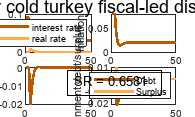

Calculating & Plotting Sacrifice ratio for fiscal-led disinflation with announcement 1 period ahead


Configuring Dynare ...
[mex] Generalized QZ.
[mex] Sylvester equation solution.
[mex] Kronecker products.
[mex] Sparse kronecker products.
[mex] Local state space iteration (second order).
[mex] Bytecode evaluation.
[mex] k-order perturbation solver.
[mex] k-order solution simulation.
[mex] Quasi Monte-Carlo sequence (Sobol).
[mex] Markov Switching SBVAR.

Using 64-bit preprocessor
Starting Dynare (version 4.5.6).
Starting preprocessing of the model file ...
Found 6 equation(s).
Evaluating expressions...done
Computing static model derivatives:
 - order 1
Computing dynamic model derivatives:
 - order 1
 - order 2
Processing outputs ...
done
Preprocessing completed.


STEADY-STATE RESULTS:

pi 		 0.08
x  		 -4.33681e-19
i  		 0.0900503
v  		 4.0817e-17
s  		 4.0817e-19
r  		 0

EIGENVALUES:
         Modulus             Real        Imaginary

          0.2897           0.2897                0
          0.6566           0.6566                0
           1.655            1.655             

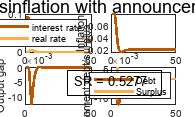

Calculating & Plotting Sacrifice ratio for fiscal-led disinflation with announcement 2 period ahead


Configuring Dynare ...
[mex] Generalized QZ.
[mex] Sylvester equation solution.
[mex] Kronecker products.
[mex] Sparse kronecker products.
[mex] Local state space iteration (second order).
[mex] Bytecode evaluation.
[mex] k-order perturbation solver.
[mex] k-order solution simulation.
[mex] Quasi Monte-Carlo sequence (Sobol).
[mex] Markov Switching SBVAR.

Using 64-bit preprocessor
Starting Dynare (version 4.5.6).
Starting preprocessing of the model file ...
Found 6 equation(s).
Evaluating expressions...done
Computing static model derivatives:
 - order 1
Computing dynamic model derivatives:
 - order 1
 - order 2
Processing outputs ...
done
Preprocessing completed.


STEADY-STATE RESULTS:

pi 		 0.08
x  		 -4.33681e-19
i  		 0.0900503
v  		 4.0817e-17
s  		 4.0817e-19
r  		 0

EIGENVALUES:
         Modulus             Real        Imaginary

          0.2897           0.2897                0
          0.6566           0.6566                0
           1.655            1.655             

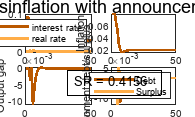

for T = 4:Tstar
    if T - 4 > 0
        message = sprintf('Calculating & Plotting Sacrifice ratio for fiscal-led disinflation with announcement %d period ahead', T-4);
        disp(message)
    else
        disp("Calculating & Plotting Sacrifice ratio for cold turkey fiscal-led disinflation")
    end
    [fig_fis{T-3}, SR_fis{T-3}] = autoplot_simple(model_name, options_,M_,oo_, inflation_target, CRPI_fis, R_fis, 4, T);
    set(gcf, 'Position', [100, 100, 1000, 600]);

    if T - 4 > 0
        graphTitle = sprintf('IRFs for fiscal-led disinflation with announcement %d period ahead', T-4);
    else
        graphTitle = 'IRFs for cold turkey fiscal-led disinflation';
    end
    suptitle(graphTitle);

    filename = fullfile(folder_path, sprintf('An%d_Fis.png', T-4));
    saveas(gcf, filename);
end

### Monetary Regime

Calculating & Plotting Sacrifice ratio for cold turkey monetary-led disinflation


Configuring Dynare ...
[mex] Generalized QZ.
[mex] Sylvester equation solution.
[mex] Kronecker products.
[mex] Sparse kronecker products.
[mex] Local state space iteration (second order).
[mex] Bytecode evaluation.
[mex] k-order perturbation solver.
[mex] k-order solution simulation.
[mex] Quasi Monte-Carlo sequence (Sobol).
[mex] Markov Switching SBVAR.

Using 64-bit preprocessor
Starting Dynare (version 4.5.6).
Starting preprocessing of the model file ...
Found 6 equation(s).
Evaluating expressions...done
Computing static model derivatives:
 - order 1
Computing dynamic model derivatives:
 - order 1
 - order 2
Processing outputs ...
done
Preprocessing completed.


STEADY-STATE RESULTS:

pi 		 0.08
x  		 -4.33681e-19
i  		 0.0900503
v  		 4.0817e-17
s  		 4.0817e-19
r  		 0

EIGENVALUES:
         Modulus             Real        Imaginary

          0.2897           0.2897                0
          0.6566           0.6566                0
           1.655            1.655             

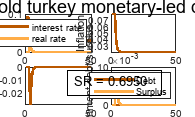

Calculating & Plotting Sacrifice ratio for monetary-led disinflation with announcement 1 period ahead


Configuring Dynare ...
[mex] Generalized QZ.
[mex] Sylvester equation solution.
[mex] Kronecker products.
[mex] Sparse kronecker products.
[mex] Local state space iteration (second order).
[mex] Bytecode evaluation.
[mex] k-order perturbation solver.
[mex] k-order solution simulation.
[mex] Quasi Monte-Carlo sequence (Sobol).
[mex] Markov Switching SBVAR.

Using 64-bit preprocessor
Starting Dynare (version 4.5.6).
Starting preprocessing of the model file ...
Found 6 equation(s).
Evaluating expressions...done
Computing static model derivatives:
 - order 1
Computing dynamic model derivatives:
 - order 1
 - order 2
Processing outputs ...
done
Preprocessing completed.


STEADY-STATE RESULTS:

pi 		 0.08
x  		 -4.33681e-19
i  		 0.0900503
v  		 4.0817e-17
s  		 4.0817e-19
r  		 0

EIGENVALUES:
         Modulus             Real        Imaginary

          0.2897           0.2897                0
          0.6566           0.6566                0
           1.655            1.655             

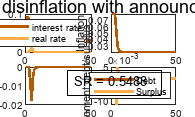

Calculating & Plotting Sacrifice ratio for monetary-led disinflation with announcement 2 period ahead


Configuring Dynare ...
[mex] Generalized QZ.
[mex] Sylvester equation solution.
[mex] Kronecker products.
[mex] Sparse kronecker products.
[mex] Local state space iteration (second order).
[mex] Bytecode evaluation.
[mex] k-order perturbation solver.
[mex] k-order solution simulation.
[mex] Quasi Monte-Carlo sequence (Sobol).
[mex] Markov Switching SBVAR.

Using 64-bit preprocessor
Starting Dynare (version 4.5.6).
Starting preprocessing of the model file ...
Found 6 equation(s).
Evaluating expressions...done
Computing static model derivatives:
 - order 1
Computing dynamic model derivatives:
 - order 1
 - order 2
Processing outputs ...
done
Preprocessing completed.


STEADY-STATE RESULTS:

pi 		 0.08
x  		 -4.33681e-19
i  		 0.0900503
v  		 4.0817e-17
s  		 4.0817e-19
r  		 0

EIGENVALUES:
         Modulus             Real        Imaginary

          0.2897           0.2897                0
          0.6566           0.6566                0
           1.655            1.655             

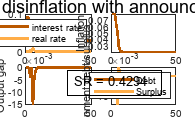

for T = 4:Tstar
    if T - 4 > 0
        message = sprintf('Calculating & Plotting Sacrifice ratio for monetary-led disinflation with announcement %d period ahead', T-4);
        disp(message)
    else
        disp("Calculating & Plotting Sacrifice ratio for cold turkey monetary-led disinflation")
    end
    [fig_mon{T-3}, SR_mon{T-3}] = autoplot_simple(model_name, options_,M_,oo_, inflation_target, CRPI_mon, R_mon, 4, T);
    set(gcf, 'Position', [100, 100, 1000, 600]);

    if T - 4 > 0
        graphTitle = sprintf('IRFs for monetary-led disinflation with announcement %d period ahead', T-4);
    else
        graphTitle = 'IRFs for cold turkey monetary-led disinflation';
    end
    suptitle(graphTitle);

   % Generate a customized filename and save the figure
    filename = fullfile(folder_path, sprintf('An%d_Mon.png', T-4));
    saveas(gcf, filename);
end

## Generate Table for Sacrifice Ratio

SR_fis_table = table([SR_fis{:}]', 'VariableNames', {'SR_fis'});
SR_mon_table = table([SR_mon{:}]', 'VariableNames', {'SR_mon'});

% Create the status variable
status = {'Cold-turkey'; 'Announced 1'; 'Announced 2'};

% Create a table from the status variable
status_table = table(status, 'VariableNames', {'Status'});

% Concatenate the tables horizontally
combined_table = [status_table, SR_fis_table, SR_mon_table];